## **Set up Cluster Profile**

If your computing task is too big or too slow for your local computer, you can offload your calculation to a cluster onsite or in the cloud. 

Before you can run the next sections, you must get access to a cluster. 

1. On the MATLAB Home tab, go to **Parallel > Discover Clusters** to find out if you already have access to a cluster with MATLAB Parallel Server™. Click **Next** on *Cess *cluster profile. Proceed to Step 3.

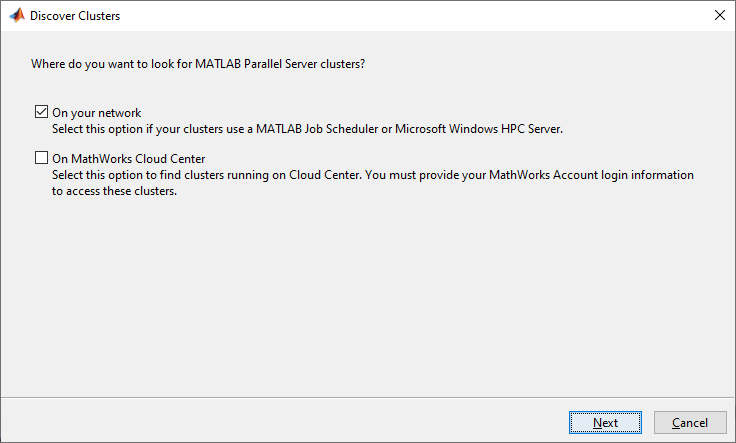

2. You can also add profile manually using file import in **Parallel** > **Create and Manage Clusters**. The *Cess* cluster profile can be downloaded [here](https://github.com/cess-lab/.github-private/blob/main/Cess.mlsettings).

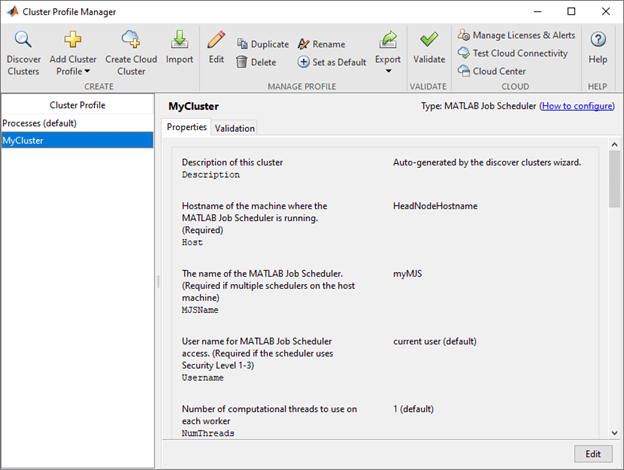

3. Click Edit to set the `Username` parameter. Set your username to one of the allowed usernames.Allowed usernames

- `khairuladib` (admin)

- `syaiful` (admin)

- `lokman`

- `caceja`

- `nurin`

- `athirah`

- `arif`

`4. `Click **Validate** in the toolbar to test the connection between your computer and the cluster. You will be prompted to set a password. The combination of your username and password ensures that only you can access (cancel, delete, retrieve outputs etc.) your jobs.

5. Display the Validation results tab so you can view the tests in progress. Ensure that all tests pass; otherwise, perform necessary troubleshooting if any tests fail.

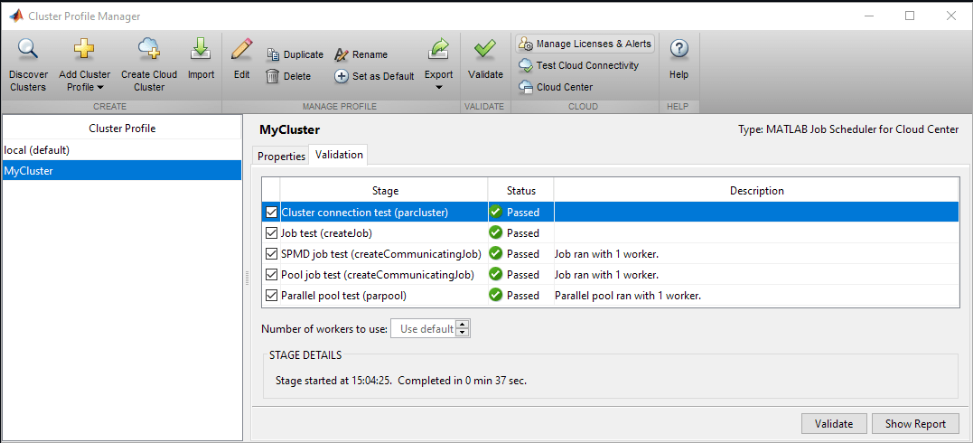

6. Make sure the profile name is set to Cess and set as default.

The cluster is now ready to use.

## **Parallel Processing Workflows**

There are two main workflows for users to opt for.

Opt for **batch processing** if you want to:

- offload the execution of long-running computations in the background without immediate interaction.

- close MATLAB/computer after submitting jobs and retrieve the results later.

- execute model training, large-scale simulations, or parameter sweeps.

`Note: You must use batch processing if your code utilizes a GPU by using functions like trainnet or gpuArray.`

Opt for **interactive processing** if you want to:

- have real-time interaction with the cluster that allows users to modify and experiment with code interactively.

- perform tasks where user input or dynamic adjustments are required during the parallel computation.

- execute iterative development, debugging, or data exploration.

### Batch Processing

`The command to perform batch jobs is asynchronous, which means that your client MATLAB session is not blocked, and you can ``continue your own interactive session while the cluster is busy evaluating your code``.`

1. Submitting a batch job using the function `batch`.

Job = batch(Script)

Starting parallel pool (parpool) using the 'Cess' profile ...
Connected to parallel pool with 8 workers (PreferredPoolNumWorkers).

ans = 

 ClusterPool with properties: 

            Connected: true
           NumWorkers: 8
                 Busy: false
              Cluster: 

This will run the script file script on a worker in the cluster specified by the default cluster profile. (Note: Do not include the `.m` file extension with the script name.) 

The function returns `Job`, a handle to the job object that runs the script. The script file script is copied to the worker. By default, workspace variables are copied from the client to workers in the cluster.

If you want to block MATLAB until the job finishes, use the `wait` function on the job object:

wait(Job);

Unrecognized function or variable 'NumWorkers'.

By default, MATLAB saves the Command Window output from the batch job to the diary of the job. To retrieve it, use the `diary` function:

diary(job)

2. Optionally, specify pairs of arguments as `Name = Value`:

- `Workspace`— Variables to copy to workers structure scalar

- `Profile` — Cluster profile

- `AdditionalPaths` — Paths to add to workers

- `AttachedFiles` — Files or folders to transfer

- `AutoAddClientPath` — Flag to add user-added entries on client path to worker path

- `AutoAttachFiles` — Flag to enable dependency analysis

- `Pool` — Number of workers to make into a parallel pool

Refer the [`batch`](https://www.mathworks.com/help/parallel-computing/batch.html) documentation for more details.

3. Monitor the job using Job Monitor.

The Job Monitor displays the jobs in the queue for the scheduler determined by your selection of a cluster profile. Open the Job Monitor from the MATLAB desktop on the **Home** tab in the **Environment** section, by selecting **Parallel > Monitor Jobs**.

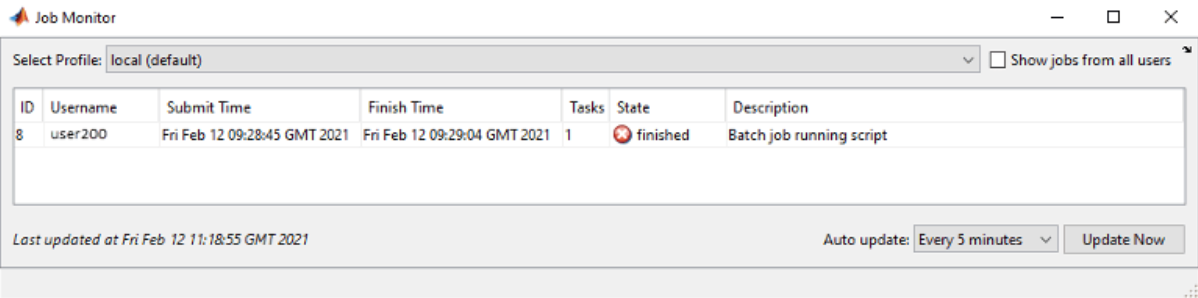

The Job Monitor lists all the jobs that exist for the cluster specified in the selected profile. You can choose any one of your profiles, and whether to display jobs from all users or only your own jobs.

4. Fetch results and clean up job data.

Use the load function to fetch the results.

load(Job,'x'); % Loads only a variable called 'x' that is produced during the batch job.
load(Job); % Loads all variables that are produced in the cluster's workspace.

When you have loaded all the required variables, delete the job object to clean up its data and avoid consuming resources unnecessarily:

delete(Job);
clear Job

#### Try it Yourself!

### Interactive Processing

`A parallel pool is a set of MATLAB workers on the cluster. The pool workers can be used interactively and communicate with each other during the lifetime of the job. You can have ``only one parallel pool at a time from a MATLAB client session``.`

There are three options to access cluster interactively which includes [`parfor`](https://www.mathworks.com/help/parallel-computing/parfor.html), [`spmd`](https://www.mathworks.com/help/parallel-computing/spmd.html), or [`tall`](https://www.mathworks.com/help/matlab/ref/tall.tall.html).

1. Open a parallel pool.

To open a parallel pool based on your default settings:

parpool

You can also specify number of workers used in the cluster:

%NumWorker=?
%parpool(NumWorkers)

2. Executing parallel code using `parfor`

When MATLAB encounters a parallelized code, it sends the code and necessary data to the cluster, executes on the cluster workers, and fetches the output back to your computer.

tic
n = 200;
A = 500;
a = zeros(1,n);
parfor i = 1:n
    a(i) = max(abs(eig(rand(A))));
end
toc

You can see this happens inside a `parfor` block when the following message appears in your Command Window:

`Analyzing and transferring files to the workers ...done.`

`3. `Executing serial code using `spmd`

If your code is fully serial, but you want it to run on the cluster to utilize the benefit of higher processing capabilities, use `spmd` as a workaround. You can transfer your workspace variables to the cluster and run your code there by enclosing the code in an `spmd` block as such:

spmd (1)
    tic
    n = 200;
    A = 500;
    a = zeros(1,n);
    for i = 1:n
        a(i) = max(abs(eig(rand(A))));
    end
    toc
end

For this purpose, we want to set `n = 1` so that only one cluster worker is used. 

Variables created or modified inside an `spmd` block become [composite](https://www.mathworks.com/help/parallel-computing/composite.html) objects. A composite object can later be used inside other `spmd` blocks, so minimal changes to your code are required. A composite object resembles a cell array; hence, accessing it by using curly braces like `MyComposite{1}` outside an `spmd` block will convert it back to its original data type.

Result = a{1};